Creating the Learning Factory Environment

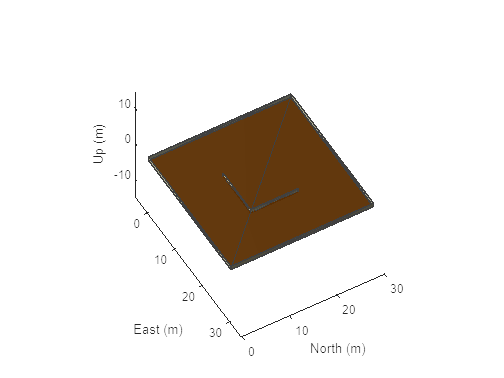

envc = EnvironmentConstants();
[obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment1();
show3D(scenario);
lightangle(-45,30);
view(60,50);

Reinforcement Learning stuff

points = [];
counter = 0

counter = 0

rng(0)
while counter < 12
    counter = counter + 1;

    isvalid = false;
    while ~isvalid        
        rows = randperm(gridSize(1),1);
        cols = randperm(gridSize(2),1);
        position = [rows' cols'];
        if ~isempty(points)
            if ~any(ismember(position, obstacles, 'rows')) && ~any(ismember(position, points, 'rows')) 
                isvalid = true;
                points = [points; position];
            end
        elseif ~any(ismember(position, obstacles, 'rows')) 
            isvalid = true;
            points = position;
        end
    end
end
points

points =     25    28
     4    28
    19     3
     9    17
    29    29
     5    30
    29    15
    25     5
    13    28
    24    29


fname = sprintf('experiment_points/experiment_1_points', 'points');
save(fname)
 